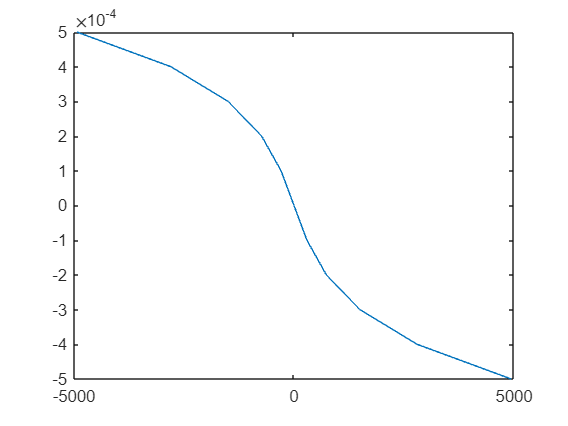

% 入射波右边界的模态节点位移Φ和模态力T(入射第二阶模态,频率wd,波数kd,)

%% 输入量

n = 1;
Kd = kd(n);

CL = 6.35e3;
CT = 3.13e3;

k = Kd/h;
w = wd*CT/h;
x = Coordinate(bnd_R,1);
y = Coordinate(bnd_R,2);

p = sqrt((w/CL)^2-k^2);
q = sqrt((w/CT)^2-k^2);

E = [exp(1i*p*y) exp(-1i*p*y) exp(1i*q*y) exp(-1i*q*y)];
A = Amp(:,n);
u =  E * diag([k, k, -q, q].*1i) * A .* exp(1i*k*x);
v =  E * diag([p, -p k k].*1i) * A .* exp(1i*k*x);
t11 = E * diag([mu*(2*p^2-q^2-k^2)*[1 1], 2*mu*q*k*[1 -1]]) * A .* exp(1i*k*x);
t12 = E * diag([2*mu*k*p*[-1 1], mu*(q^2-k^2)*[1 1]]) * A .* exp(1i*k*x);
t22 = E * diag([-mu*(q^2-k^2)*[1 1], 2*mu*k*q*[-1 1]]) * A .* exp(1i*k*x);


% 绘图检验
[y1,I] = sort(y);
plot(real(u(I)),y1)